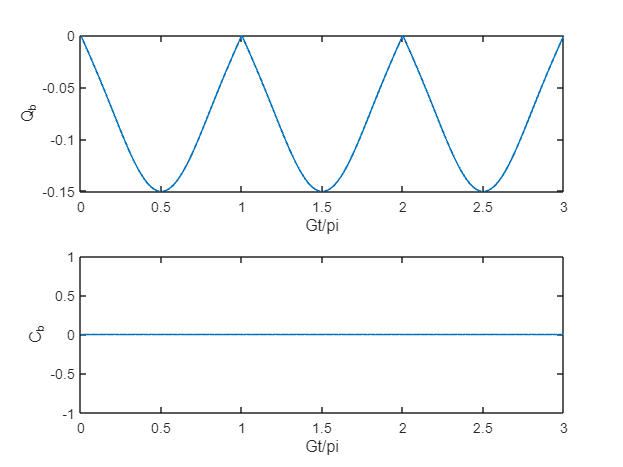

Gt=0:0.01*pi:3*pi;


%Coefficients-----------------------------
abs_x1=cos(Gt/2).^2;
abs_x2=sin(Gt/2).^2;
abs_x3=1/2*abs(sin(Gt));
abs_x4=abs_x3;

abs_x1_2=1/sqrt(2)*abs(cos(Gt/2));
abs_x2_2=abs_x1_2;
abs_x3_2=1/sqrt(2)*abs(sin(Gt/2));
abs_x4_2=abs_x3_2;
%CAB--------------------------------------

Con_AB=2*(1/2*4/9*cos(Gt/2).^2-sqrt(1/3*cos(Gt/2).^4).*(1/3*sin(Gt/2).^4 +2/3*sin(Gt/2).^2));
Con_AB_cut=max(0,Con_AB);

% figure;
% subplot(2,1,1)
% plot(Gt/pi, Con_AB,LineWidth=1);
% xlabel('Gt/pi');
% ylabel('Q_A_B');
% 
% subplot(2,1,2)
% plot(Gt/pi,Con_AB_cut,LineWidth=1);
% xlabel('Gt/pi');
% ylabel('C_A_B');

%Cab----------------------------------------
a_ab=1/3*abs_x1.^2 + 2/3*abs_x1_2.^2 + 2/3*abs_x2_2.^2;
d_ab=1/3*abs_x2.^2;
z_ab=4/9*abs_x3_2.*abs_x4_2;

Con_ab=2*(z_ab-sqrt(a_ab.*d_ab));
Con_ab_cut=max(0,Con_ab);

% figure;
% subplot(2,1,1)
% plot(Gt/pi, Con_ab,LineWidth=1);
% xlabel('Gt/pi');
% ylabel('Q_a_b');
% 
% subplot(2,1,2)
% plot(Gt/pi,Con_ab_cut,LineWidth=1);
% xlabel('Gt/pi');
% ylabel('C_a_b');

%CAb---------------------------------------
z_Ab=4/9*abs_x1_2.*abs_x4_2;
a_Ab=1/3*abs_x4.^2 + 2/3*(abs_x3_2.^2 + abs_x2_2.^2);
d_Ab=1/3*abs_x3.^2;

Con_Ab=2*(z_Ab-sqrt(a_Ab.*d_Ab));
Con_Ab_cut=max(0,Con_Ab);

figure;
subplot(2,1,1)
plot(Gt/pi, Con_Ab,LineWidth=1);
xlabel('Gt/pi');
ylabel('Q_A_b');

subplot(2,1,2)
plot(Gt/pi,Con_Ab_cut,LineWidth=1);
xlabel('Gt/pi');
ylabel('C_A_b');

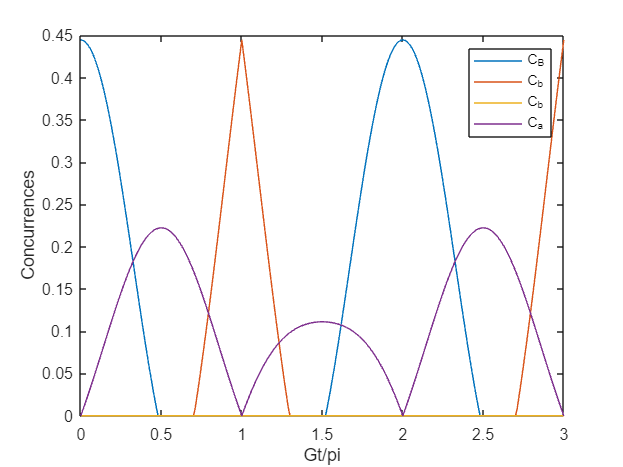


%CAa---------------------------------------
z_Aa=abs(3/18*sin(Gt)+1/18*sin(Gt).^2);

Con_Aa=z_Aa;
Con_Aa_cut=max(0, Con_Aa);

% figure;
% subplot(2,1,1)
% plot(Gt/pi, Con_Aa,LineWidth=1);
% xlabel('Gt/pi');
% ylabel('Q_A_a');
% 
% subplot(2,1,2)
% plot(Gt/pi,Con_Aa_cut,LineWidth=1);
% xlabel('Gt/pi');
% ylabel('C_A_a');

%All plots at once
figure;
plot(Gt/pi, Con_AB_cut);
hold on;
plot(Gt/pi,Con_ab_cut);
plot(Gt/pi,Con_Ab_cut);
plot(Gt/pi,Con_Aa_cut);
xlabel('Gt/pi');
ylabel('Concurrences');
legend('C_A_B', 'C_a_b', 'C_A_b', 'C_A_a');

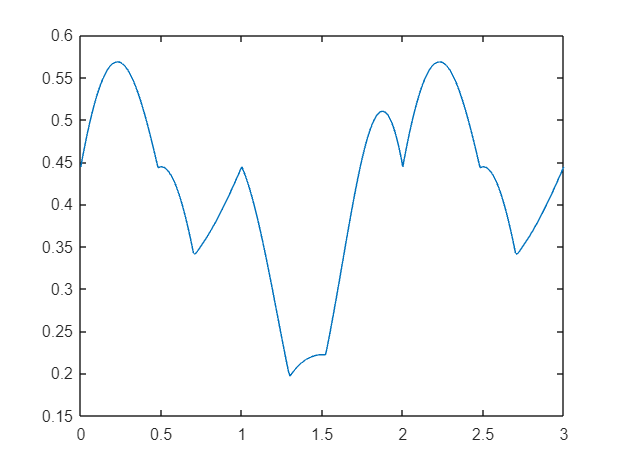


Conservation=Con_AB_cut+Con_ab_cut +2*Con_Aa_cut;
figure;
plot(Gt/pi, Conservation);